close all
clc
disp('Elias Assaf 315284729 - Jameel Nassar 206985152')

Elias Assaf 315284729 - Jameel Nassar 206985152


### Section 1

%% Section 1.1
cameraman = imread("cameraman.tif");
cameraman = double(cameraman)/256;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% Section 1.2


To filter the image, we first build 2 filters, one for the x axis and one for the y axis, we apply both filters on the image using conv2() with the 'same' arguement so we don't have to deal with the edges.

to get the magnitude we first take the filtered images to the power of 2, sum them and we take the square root of the sum, i.e:


$$mag = \sqrt{x^2+y^2}$$


where x is the filtered image using G_px filter, y is the filtered image using G_py filter, and the power operator applied to each element of the matrix separately, i.e matlab .^ operator.

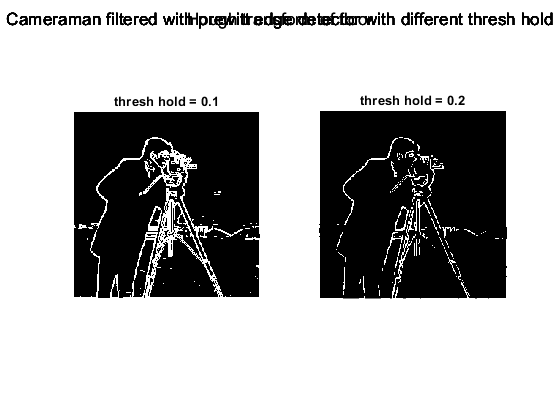

figure;sgtitle("Cameraman filtered with prewitt edge detector with different thresh hold");
cameraman_prewitt_mag_1 = dip_prewitt_edge(cameraman, 0.1);
cameraman_prewitt_mag_2 = dip_prewitt_edge(cameraman, 0.2);
subplot(1,2,1);imshow(cameraman_prewitt_mag_1);title("thresh hold = 0.1");
subplot(1,2,2);imshow(cameraman_prewitt_mag_2);title("thresh hold = 0.2");

as we can see in the images, using the lower thresh hold doesn't remove all the edges, if for example we look under the camera we can still see some points where we have while pixel's i.e an edge, but as we increase the thresh hold we filter out those points more aggressivly and we remove most of them and in doing so we make the man edges less pronounced, and in some places such as the left middle and the right leg we lose some of the edges because they didn't pass the thresh hold.

to get the best filteration we need to look for a better thresh hold, where we remove most of the unnecessary edges but not high enough that we start losing the sharpness of the true edges.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% Section 1.3

The optional parameters of the canny edge detector (edge(I,'canny')) is the two thresh holds used to separated between weak and strong edges, where every pixel with value lower than the min thresh hold doesn't count as an edge, the pixel with values between the thresh hold is considered a weak edge, and the pixels with values greater than the max of the thresh holds are considered strong edges.

these thresh holds have no default value, when we call the function without the parameters edge function chooses them heuristically depending on the input data.

we have another optional arguement sigma, where we specifiy the sigma of the gaussian filter used in the algorithm, its default value is $\sqrt{2}$ .

note that we have 2 extra options, direction and filter, but they are not used in the canny edge detector.

we can also output along with the edges the thresh holds the function used, we can see that matlab picked [0.0313, 0.0781]

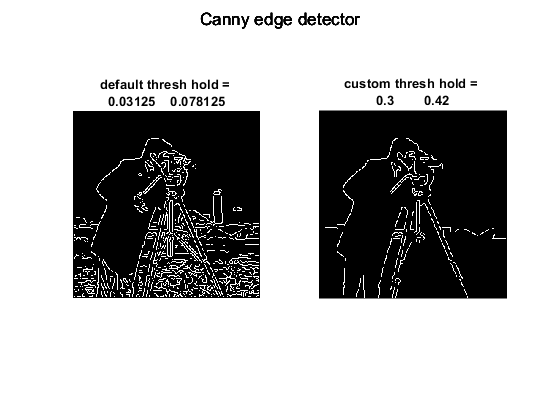

figure;sgtitle("Canny edge detector")
[cameraman_canny_default, cameraman_canny_default_threshhold] = edge(cameraman, 'Canny');
canny_thresh = [0.3 0.42];
cameraman_canny_custom = edge(cameraman, 'Canny', canny_thresh);

subplot(1,2,1);imshow(cameraman_canny_default);title(["default thresh hold = " num2str(cameraman_canny_default_threshhold)]);
subplot(1,2,2);imshow(cameraman_canny_custom);title(["custom thresh hold = " num2str(canny_thresh)]);

we can see that by increasing the thresh holds we can almost get a clear edge of the cameraman, the default values are not always good, they give a good base on where to start but as we have eyes and can think for ourselves we can try different edges to get better results, note that in automated tasks without any prior data on the images looking for an optimal thresh hold parameters manually is not very efficent, in that case we trust the ALGORITHM to give us good enough results.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Section 2

%% Section 2.1
floor = imread("floor.jpg");
floor = rgb2gray(floor)/256;
%default filter is sobel which we learned early in the course

The edge function uses the sobel method which we learned early in the course, in it we take the derivative of the images to find the images i.e where we have fast changes of magnitutde of pixels we have an edge.

we have the following optional arguements:

method: which filter to use, default value is sobel.

thresh hold: any pixel lower than this number is removed from the output image, note that some detectors such as the canny detector use 2 thresh holds., we have no default values for thresh hold, the edge picks them at run time.

direction: specifies which direction to detect the images from, i.e horizontal or vertical direction, or both, its not used in all the detectors, but for example in sobel we take a different filter for the horizontal direction or the verical (we saw in class one where we have 0 in the middle horizontal part vs 0 in the middle verical part of the filter matrix), the default values is both as in both directions.

filter: only used by zerocross method - not in our scope.

sigma: used by canny and log detectors, specifies the sigma of the gaussian filters used in these filters.

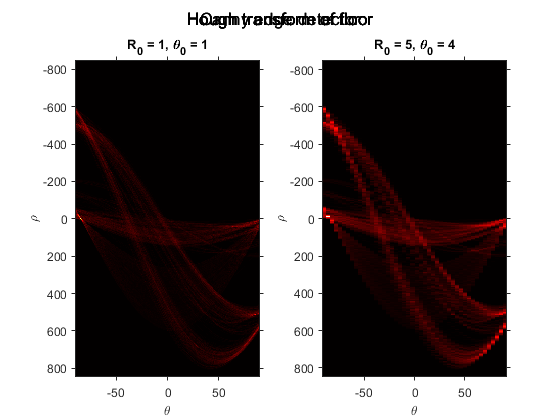

BW_floor = edge(floor);

[hough_mat_1_1,R_vec1,theta_vec1] = dip_hough_lines(BW_floor,1,1);
[hough_mat_5_4,R_vec2,theta_vec2] = dip_hough_lines(BW_floor,5,4);
figure;sgtitle('Hough transform of floor');
subplot(1,2,1);
imshow(hough_mat_1_1, [], 'XData', theta_vec2, 'YData', R_vec2);title("R_0 = 1, \theta_0 = 1");xlabel('\theta'), ylabel('\rho');
axis on, axis normal, hold on;colormap(gca,hot);


subplot(1,2,2);
imshow(hough_mat_5_4, [], 'XData', theta_vec2, 'YData', R_vec2);title("R_0 = 5, \theta_0 = 4");xlabel('\theta'), ylabel('\rho');
axis on, axis normal, hold on;colormap(gca,hot);

each element in these graph represents a vote on a possible line a with the parameters $(\rho, \theta)$ of a normal representation of a line as we saw in class

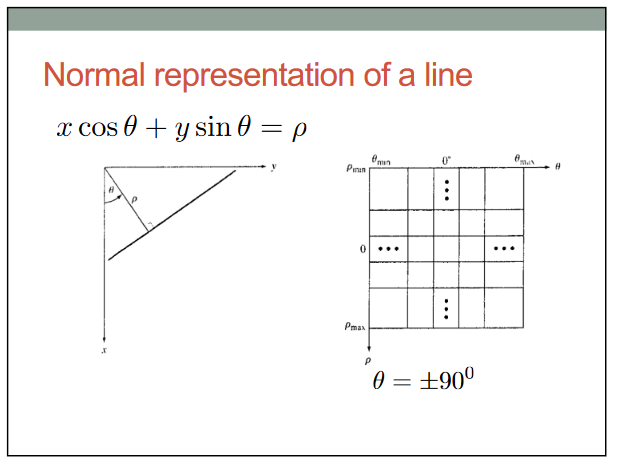


peaks_1_1 = houghpeaks(hough_mat_1_1, 4);
peaks_5_4 = houghpeaks(hough_mat_5_4, 4);


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% Section 2.2

coffee = imread("coffee.jpg");
coffee = double(rgb2gray(coffee))/256;

BW_coffee = edge(coffee);

tic;[hough_mat_circ_1_1, R_circ_vec1, theta_circ_vec1] = dip_hough_circles(BW_coffee, 1, 1);toc;

Elapsed time is 4.248331 seconds.


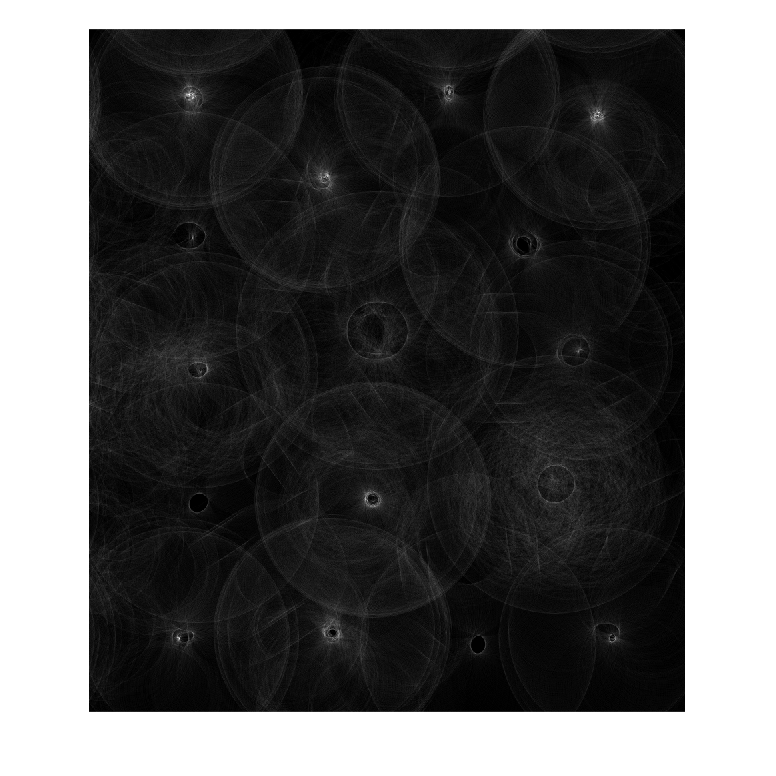

[hough_mat_circ_4_10, R_circ_vec2, theta_circ_vec2] = dip_hough_circles(BW_coffee, 4, 10);
hough_circ_peaks_1_1 = dip_houghpeaks3d(hough_mat_circ_1_1);
hough_circ_peaks_4_10 = dip_houghpeaks3d(hough_mat_circ_4_10);

figure;imshow(hough_mat_circ_1_1(:,:, 4), []);

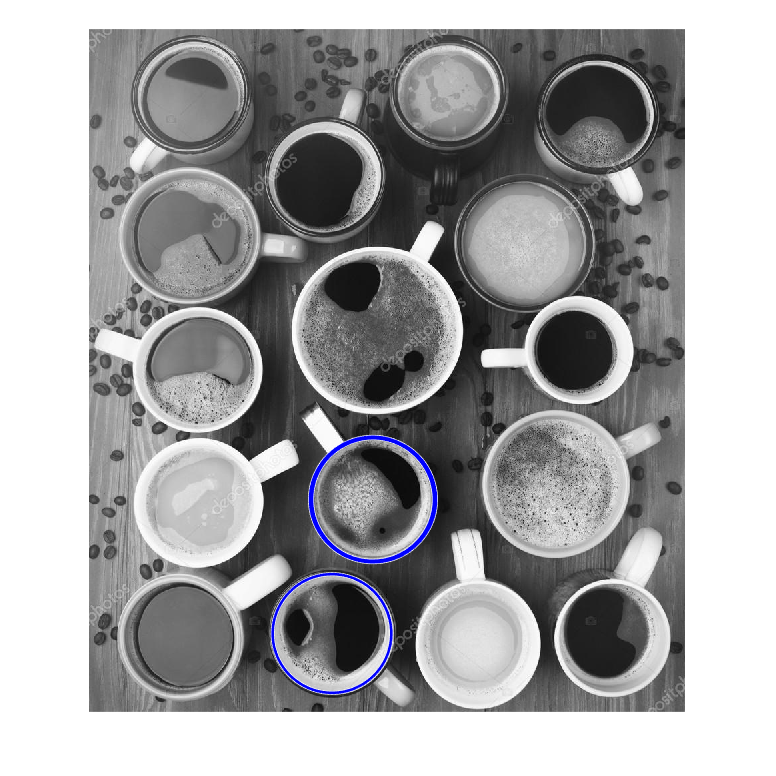

figure;imshow(coffee);hold on;
viscircles(hough_circ_peaks_1_1(:, 1:2), R_circ_vec1(hough_circ_peaks_1_1(:, 3)),'EdgeColor','b');

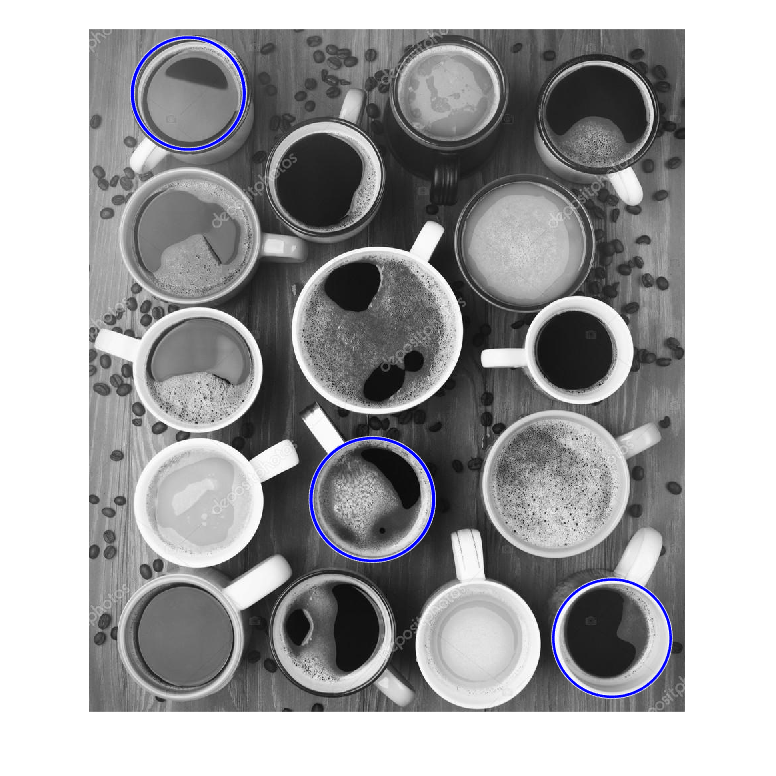


figure;imshow(coffee);hold on;
viscircles(hough_circ_peaks_4_10(:, 1:2), R_circ_vec2(hough_circ_peaks_4_10(:, 3)),'EdgeColor','b');

## Functions

function [magnitude] = dip_prewitt_edge(img, thresh)
    filt_x = 1/6 * repmat([-1 0 1], 3, 1);
    filt_y = rot90(filt_x);
    Gx = conv2(img, filt_x, 'same');
    Gy = conv2(img, filt_y, 'same');
    magnitude = sqrt(Gx.^2 + Gy.^2);
    magnitude = (magnitude >= thresh);
end

function [hough_mat, R_vec, theta_vec] = dip_hough_lines(BW, R_0, theta_0)
    
    [M,N] = size(BW);
    R_value = round(sqrt(M^2 + N^2));
    R_vec = -R_value:R_0:R_value;
    theta_vec = -90:theta_0:90;
    hough_mat = zeros(length(R_vec),length(theta_vec));
    [x_vec, y_vec] = find(BW == 1);
    x_vec = x_vec.';
    y_vec = y_vec.';

    for i = 1:length(theta_vec)
        theta = theta_vec(i) * (pi / 180);
        r = cos(theta) .* y_vec + sin(theta) .* x_vec;
        r = interp1(R_vec, R_vec, r, 'nearest');
        r = round((r+R_value + 1)/R_0);
        for j = r
            hough_mat(j, i) = hough_mat(j, i) + 1;
        end
    end

end

function [hough_mat, R_vec, theta_vec] = dip_hough_circles(BW, R_0, theta_0)

    [M,N] = size(BW);
    R_vec = 80:R_0:100;
    theta_vec = 0:theta_0:360-theta_0;
    hough_mat = zeros(M, N, length(R_vec));
    [x_vec, y_vec] = find(BW == 1);
    x_vec = x_vec.';
    y_vec = y_vec.';
    for k = 1:length(R_vec)
        r = R_vec(k);
        for i = 1:length(theta_vec)
            theta = theta_vec(i) * (pi / 180);
            a = abs(round(x_vec - r*cos(theta)));
            b = abs(round(y_vec - r*sin(theta)));
            a_w = a(a>0 & b>0 & a<=M & b<=N);
            b_w = b(a>0 & b>0 & a<=M & b<=N);
            for j=1:length(a_w)
                hough_mat(a_w(j), b_w(j), k) = hough_mat(a_w(j), b_w(j), k) + 1;
            end
        end
    end

end

function [peaks] = dip_houghpeaks3d(H)
    peaks = dip_houghpeaks3d_custom(H, 5);
end

function [peaks] = dip_houghpeaks3d_custom(H, numOfPeaks)
    peaks = zeros(numOfPeaks, 3);
    for i = 1:numOfPeaks
        [val, idx] = max(H(:));
        [idx1, idx2, idx3] = ind2sub(size(H), idx);
        peaks(i, :) = [idx2, idx1, idx3];
        H(idx1, idx2, idx3) = 0;
    end
end
